## **5.3 Evaluation Procedure**

### *5.3.1 Scenario 1: MATLAB Interactive Editor*

#### *1.1 File Mode*

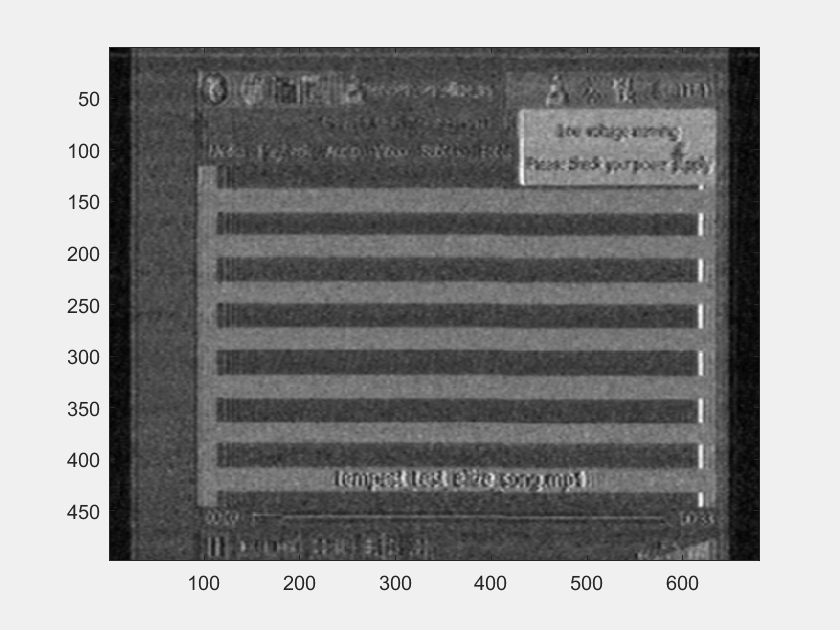

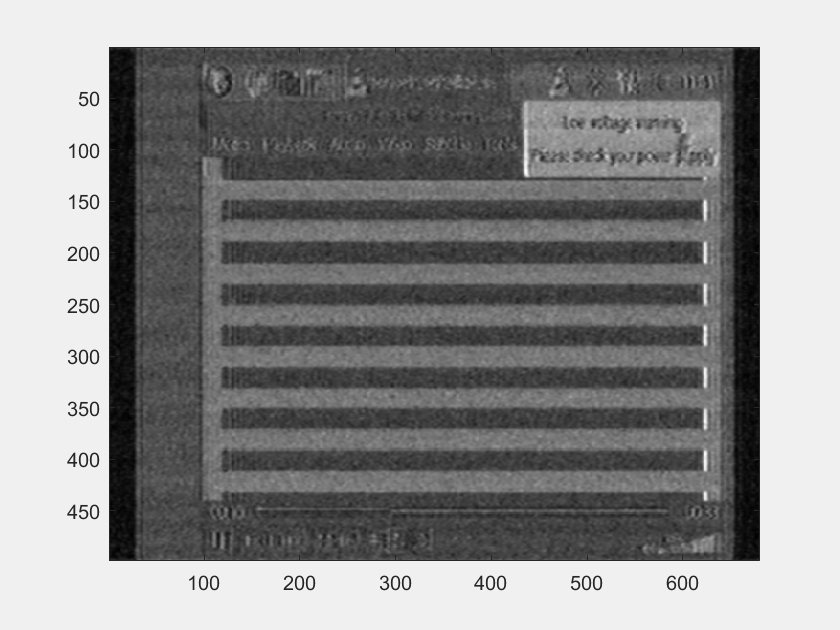

clear all;
close;
clc;

uicontrol('Visible','off');

videoModes = Modes;
demodulator = AMDemodulation();
resample = Resampling();
sync = SyncDetection();
reshaped = Reshape();

input = InputSignalViaFile('Demo/recording.wav');
input_signal = input.getSignal;
sample_rate = input.getSampleRate;

frame = FrameDetection(sample_rate, input_signal, videoModes.getVideoModes);
frame_height = 498; % = frame.getFrameHeight;
frame_width = 680; % = frame.getFrameWidth;
refresh_rate = frame.getRefreshRate;
pixels_per_frame = frame_height*frame_width;
pixel_rate = round(frame_width*frame_height*refresh_rate);

filter_magnitude = 1.1;
h_offset = -18;
v_offset = -65;

wav_file = dsp.AudioFileReader('Demo/recording.wav');
num_samples = round(frame_height*frame_width*round(pixel_rate/sample_rate));
wav_file.SamplesPerFrame = num_samples;
starting_sample = 1;
total_samples = input.getSampleNum;

while (starting_sample < total_samples-starting_sample)
    in = wav_file();

    demod_signal = process(demodulator, in, 'File');
    resampled_signal = process(resample, demod_signal(1:num_samples-1), pixel_rate, sample_rate);
    reshaped_signal = process(reshaped, resampled_signal, pixels_per_frame, frame_height, frame_width, filter_magnitude);
    synced_signal = process(sync, reshaped_signal, h_offset, v_offset);
    
    image(synced_signal, 'CDataMapping','scaled');
    colormap(gray(255));
    drawnow

    starting_sample = starting_sample+num_samples;
end

release(wav_file)

#### *1.2 SDR Mode*

clear all;
close;
clc;

uicontrol('Visible','off');

videoModes = Modes;
demodulator = AMDemodulation();
resample = Resampling();
sync = SyncDetection();
reshaped = Reshape();

input = InputSignalViaRSP;

API Open
MaxDevs=6 NumDevs=1
chosenDevice = 735C6C6100000000
RSP1A device successfully selected


input.SampleRateMHz = 8;
input.FrequencyMHz = 190;
input.Bandwidth = 6000;

input.Stream;

Initialised!


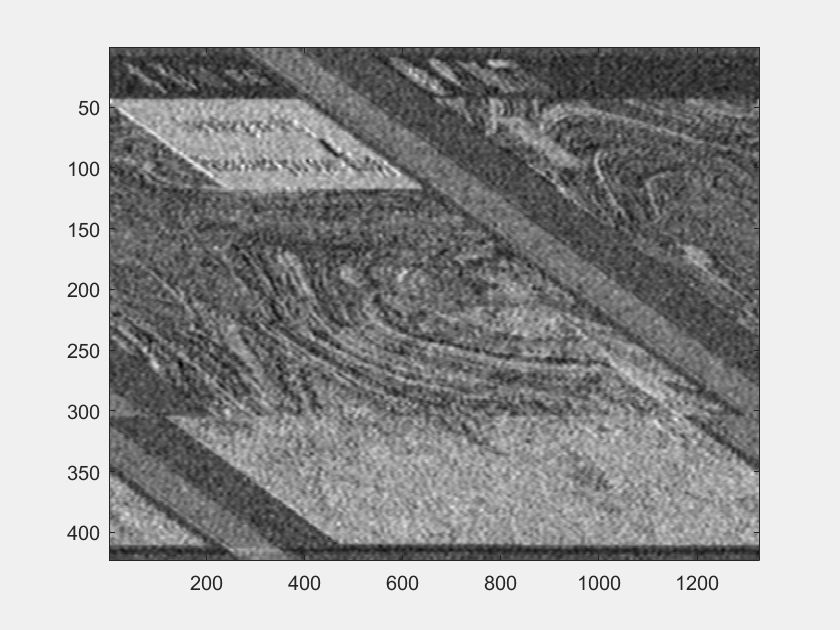

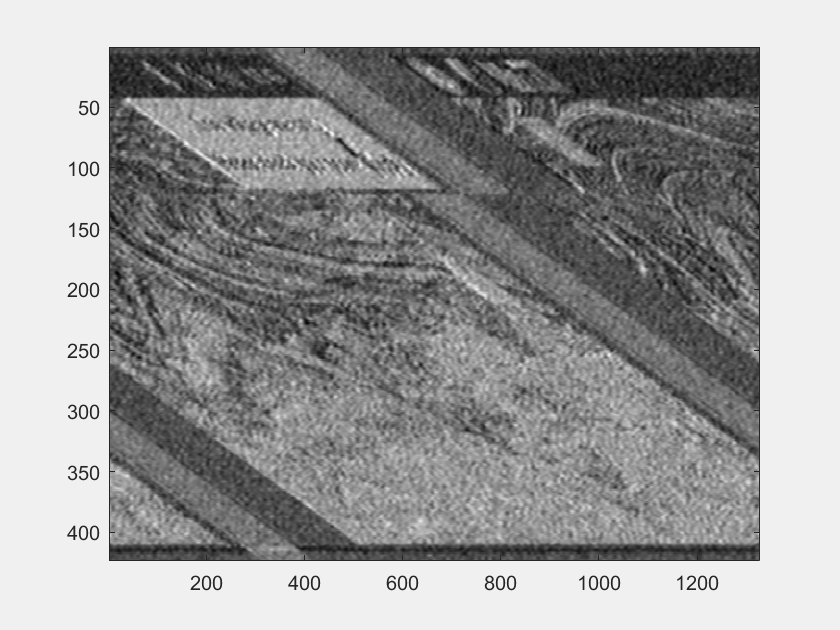


sample_rate = input.SampleRateMHz*1e6;
Time2Fill_Buffer = 2e6/sample_rate;
pause(Time2Fill_Buffer);
input_signal = RSP_MEX('data');

frame = FrameDetection(sample_rate, input_signal, videoModes.getVideoModes);
frame_height = frame.getFrameHeight;
frame_width = frame.getFrameWidth;
refresh_rate = frame.getRefreshRate;
pixels_per_frame = frame_height*frame_width;
pixel_rate = frame.getPixelRate;
filter_magnitude = 1.1;
h_offset = 0;
v_offset = 0;

total_duration = 60;
for i = 0:total_duration/Time2Fill_Buffer
    in = RSP_MEX('data');

    demod_signal = process(demodulator, in, 'SDR');
    resampled_signal = process(resample, demod_signal, pixel_rate, sample_rate);
    reshaped_signal = process(reshaped, resampled_signal, pixels_per_frame, frame_height, frame_width, filter_magnitude);
    synced_signal = process(sync, reshaped_signal, h_offset, v_offset);

    image(synced_signal, 'CDataMapping','scaled'); 
    colormap(gray(255));
    drawnow

    pause(Time2Fill_Buffer)
end


input.StopStream;

Uninitialised!


input.Close;

Released!


delete(input);

## 5.4 Results			

### *5.4.1 Accuracy of Synchronisation Information*

#### *Figure 5.2*

clear all;

API Close


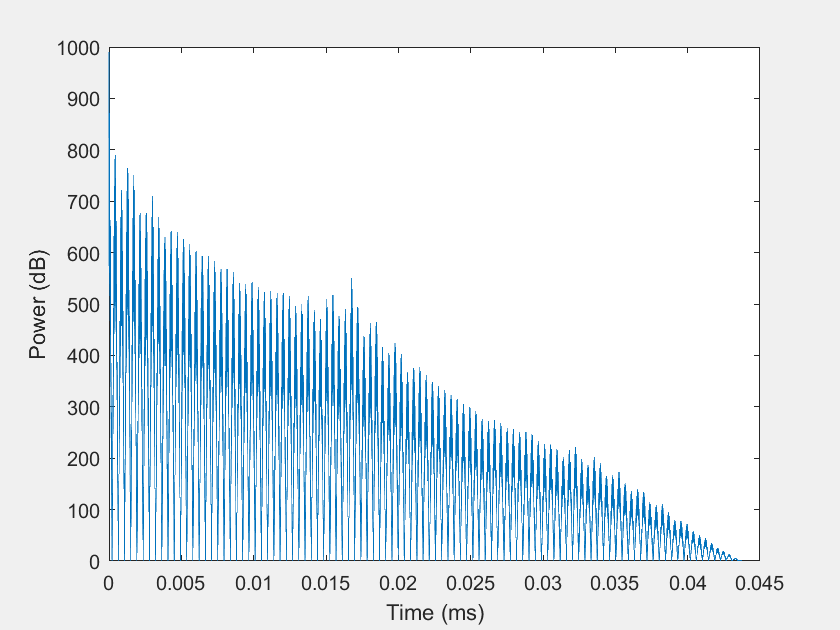

close;
clc;

uicontrol('Visible','off');

input = InputSignalViaFile('Demo/recording.wav');
input_signal = input.getSignal;
sample_rate = input.getSampleRate;

x = input_signal([1:350000-1,1]);
[xcorr_signal, lags] = xcorr(x,x);
xcorr_signal_section = xcorr_signal(round(length(xcorr_signal)/2):length(xcorr_signal));
abs_signal = abs(xcorr_signal_section);
t = 0:length(abs_signal)-1;
t = t./sample_rate;
plot(t, abs_signal); xlabel('Time (ms)'); ylabel('Power (dB)');